## **Convolution In Practice**

**Create a bunch of signals**

f1 = 20; % 20 Hz signal
ts = 1/100; % sampling rate
T = 3; % total time
t = 0 : ts : T; % time interval
signal_20hz = sin(2*pi*f1*t);
plot(signal_20hz)
f2 = 1; % 1 Hz
signal_1hz = sin(2*pi*f2*t);
plot(signal_1hz);

**Add the two signals**

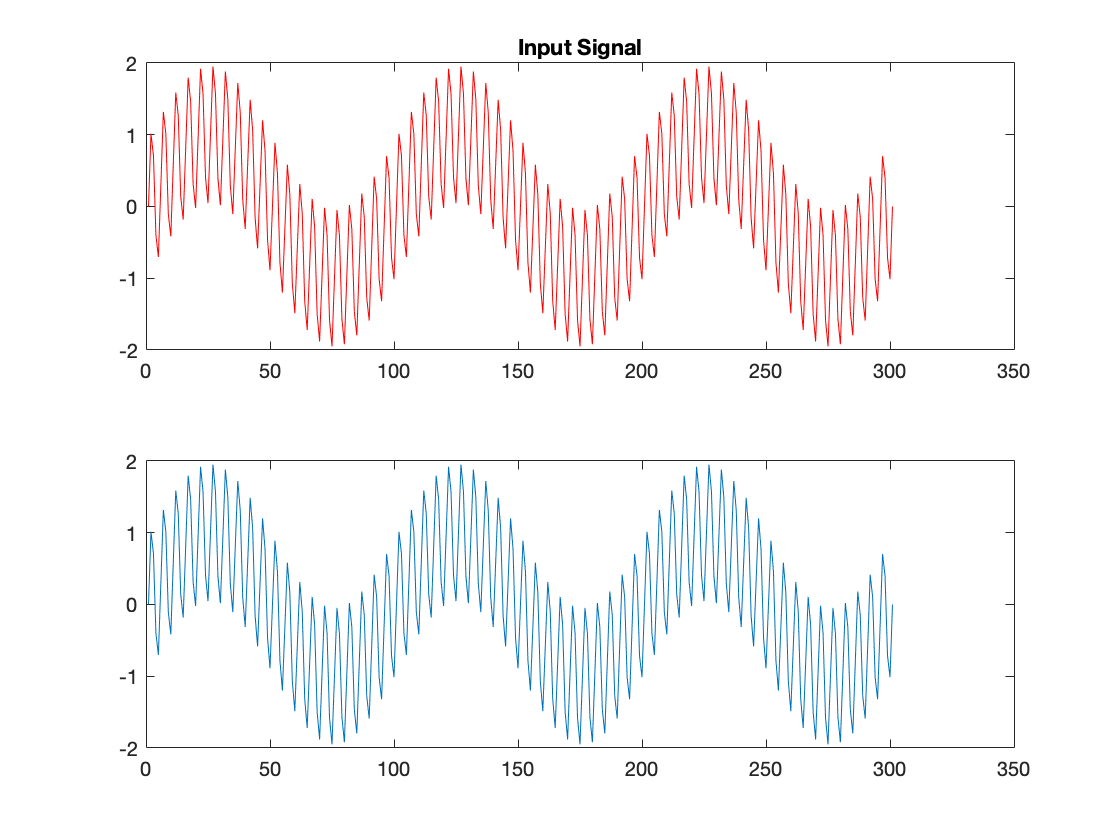

signal_20hz_1hz = signal_20hz + signal_1hz;
plot(signal_20hz_1hz);

## **Filter Design**

**Design a filter via fdatool**

% fdatool
plot(Imp_Response)

**Convolution time**

output_signal = conv(signal_20hz_1hz, Imp_Response);

**Now plot them all on subplots**

subplot(3,1,1)
plot(signal_20hz_1hz)
title('Input signal with noise')

subplot(3,1,2)
plot(Imp_Response)
title('Impulse Response')

subplot(3,1,3)
plot(output_signal)
title('Output Signal')

## **Running sum of a signal**

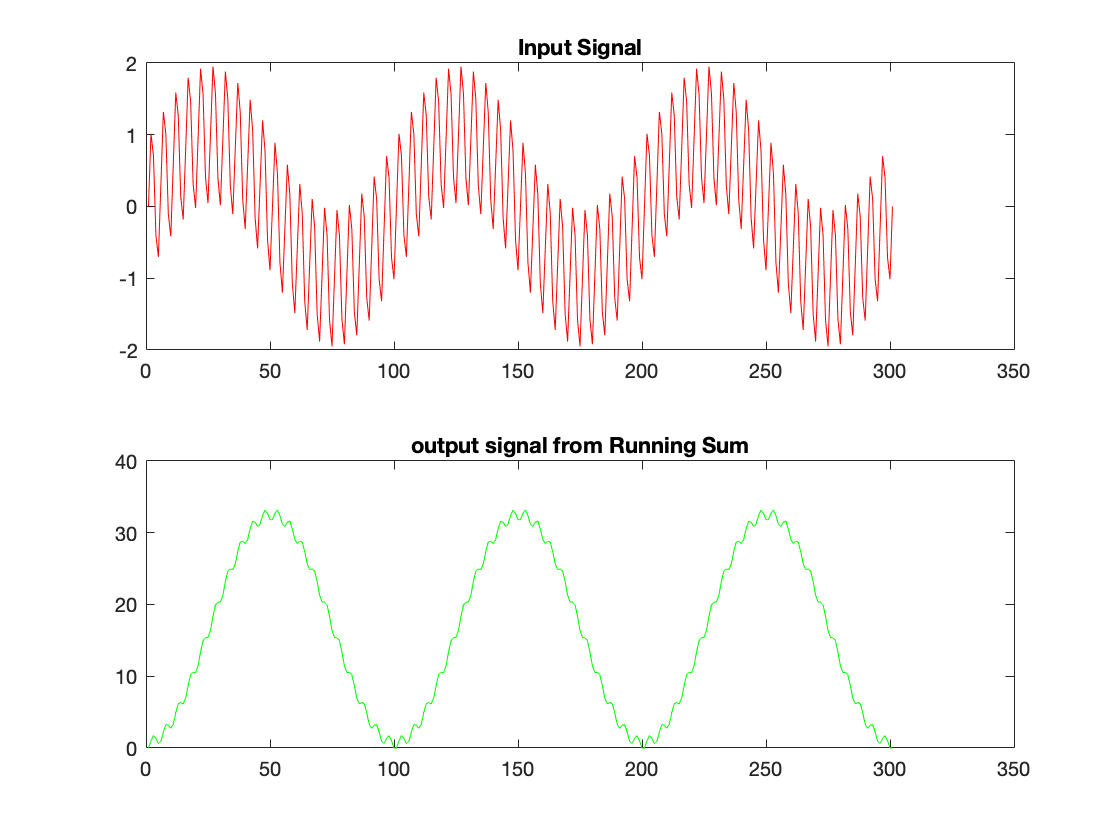

input_signal = signal_20hz_1hz;
plot(input_signal)
output_signal_2 = cumsum(input_signal);
subplot(2,1,1)
plot(input_signal, 'r')
title('Input Signal')
subplot(212)
plot(output_signal_2, 'g')
title('output signal from Running Sum')

**The running sum should help with peak detection**

## **First Difference of a Signal**

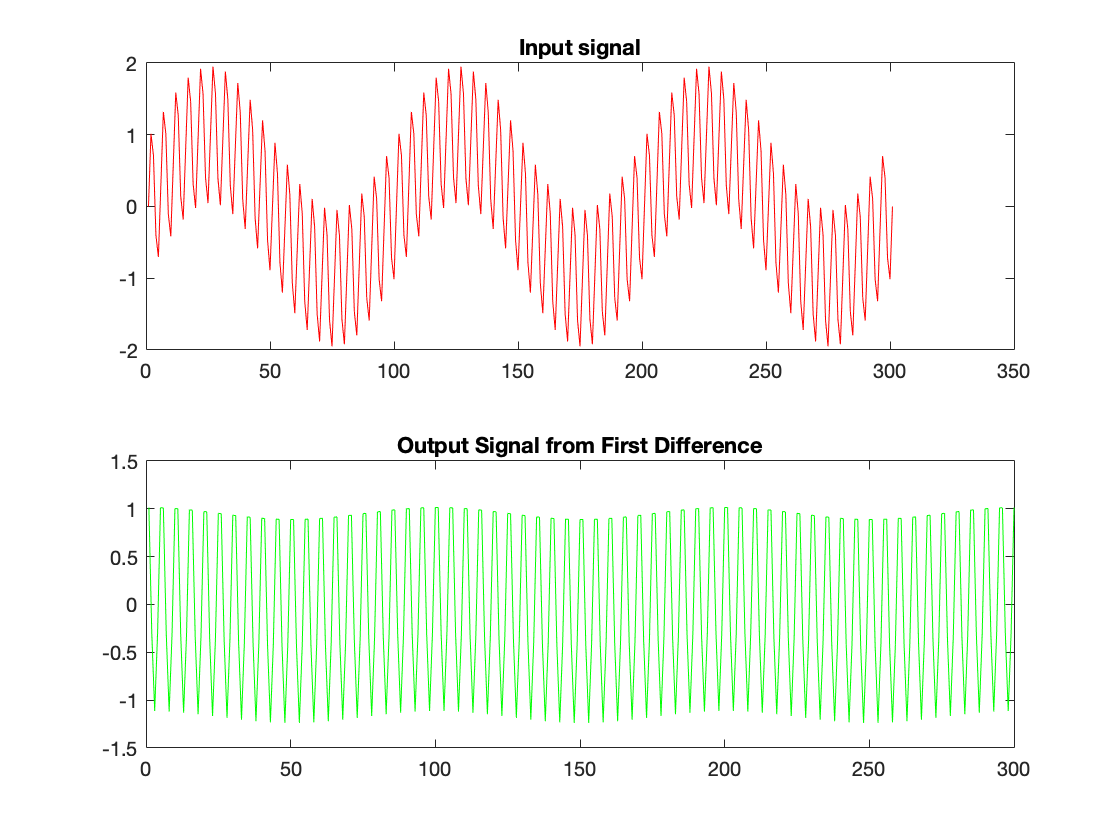

input_signal = signal_20hz_1hz;
output_signal_3 = diff(input_signal);
subplot(211)
plot(input_signal, 'r')
title('Input signal')
subplot(212)
plot(output_signal_3, 'g')
title('Output Signal from First Difference')